# Classify human electrocardiogram (ECG) Signals

**Name:**     Zaid Gul                                                                                           **Matrikelnummer:**  977254     

## Continuous Wavelet Transform (CWT) 

### **ECG Signals Database Preparartion**

close all
clear all

if isfolder('CWT')
   rmdir('CWT', 's');
end


%ECG Database
load ('ECGData.mat'); % Loading ECG database

data = ECGData.Data; % Getting Database
% The variable "data" is a matrix of 162 x 65536. It means it carries
% a total of 162 ECG signals of size 65536 samples each. 


labels = ECGData.Labels; %Getting Labels
% From Labels, we get types of ECG signals information.That is,

% 1:96 are ARR Signals (96)
% 97:126 are CHF Signals (30)
% 127:162 are NSR Signals (36)



% Each recording is of 65,536 samples therefore, it can be broken 
% into small signals of length 500 samples to increase the size of
% database to make it appropriate to train a CNN. 

% For this purpose, we take 30 recordings of each type (ARR, CHF, 
% NSR) to have equal distribution. Each recording is broken in to
% 10 pieces of length of 500 samples. Therefore, each category will
% provide 300 recordings of size 500 samples and total will be 900 
% recordings. Out of 900 (30x10) recordings, 750 will be used for 
% training and 150 will be used for testing.

ARR = data (1:30,:); %Taken first 30 Recordings
CHF = data (97:126, :); %Taken first 30 Recordings
NSR = data (127:156, :); %Taken first 30 Recordings

#### Plot the Signals

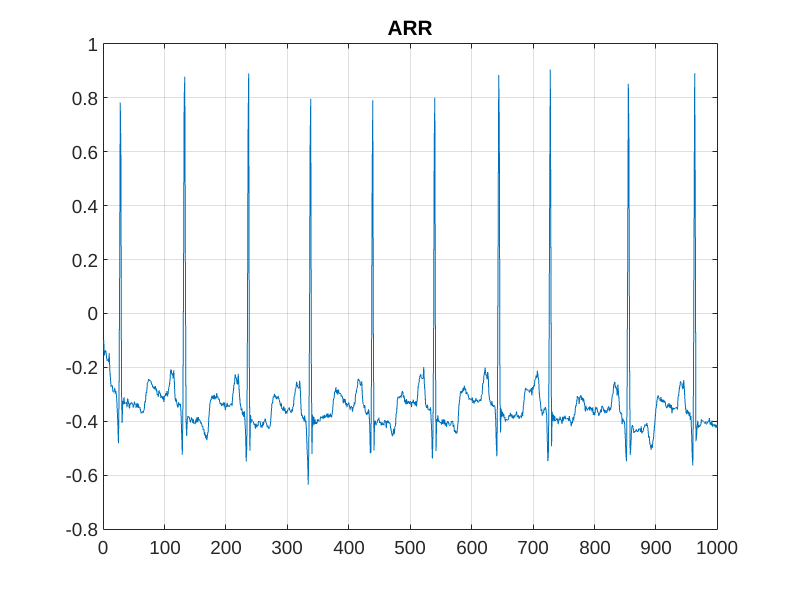

% Plot ARR
plot(ARR(1, 1:1000));
title('ARR');
grid on

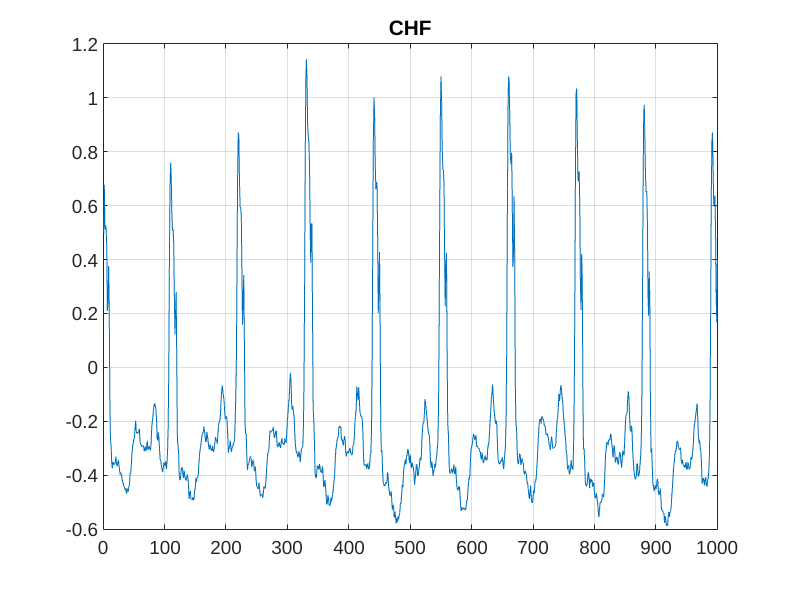

% Plot CHF
plot(CHF(1, 1:1000));
title('CHF');
grid on

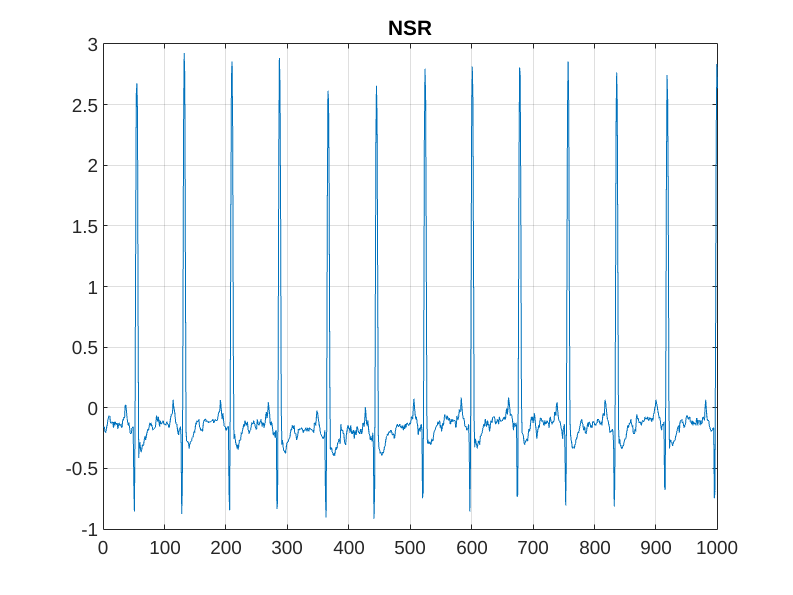

% Plot NSR
plot(NSR(1, 1:1000));
title('NSR');
grid on

#### Continuous Wavelet Transform (CWT) 

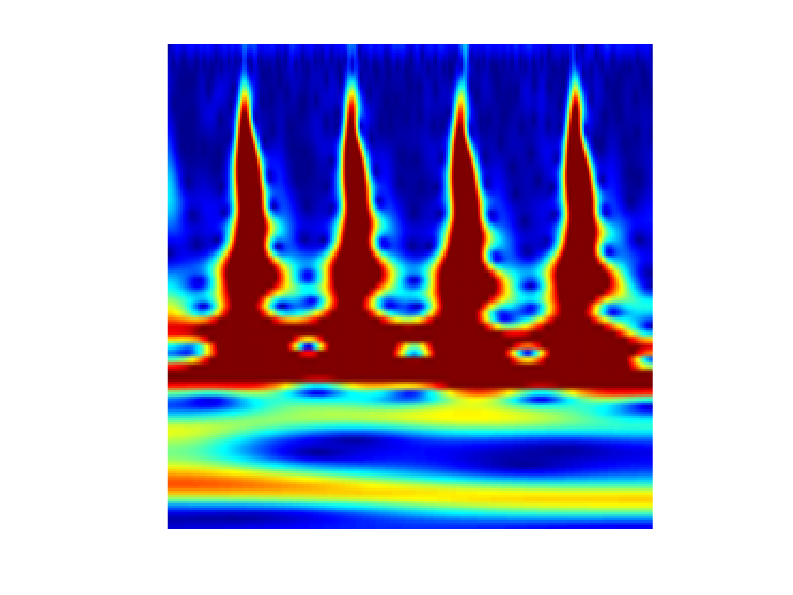

%Defining filters for CWT with 12 filters per octave

% In wavelet analysis, a voice refers to a specific scale of the wavelet function. 
% Increasing the number of voices per octave provides better frequency resolution but also 
% increases computational complexity. Here, it is set to 12 voices per octave, striking a balance 
% between accuracy and efficiency.

signallength=500; % Signal Length
Fs = 128; % Sampling Frequency
fb = cwtfilterbank('SignalLength',signallength, 'SamplingFrequency', Fs, 'VoicesPerOctave', 12);

% The CWT filter bank object, 'fb', is created using the specified parameters, enabling further analysis
% and processing of the input signal using wavelet transforms.


% MATLAB function 'ecg2cwt' takes ECG data and a CWT filter bank 
% object as inputs and generates a set of CWT images for each ECG signal.
% images of size 227 x 227 x 3

% A cell array that stores the generated CWT images for each ECG signal.
arrImages = ecg2cwt(ARR, fb);
chfImages = ecg2cwt(CHF, fb);
nsrImages = ecg2cwt(NSR, fb);

% Scalogram is converted in to image and saved in folders corresponding
% to each class. Each image is of size 227x227 in RGB color format. 
% After conversion we have total 900 scalogram images.
% For each signal the number of images is 300. 

%Display sample of each ARR, CHF, NSR
imageIndex = 30;

% Display the selected ARR image
imshow(arrImages{imageIndex});

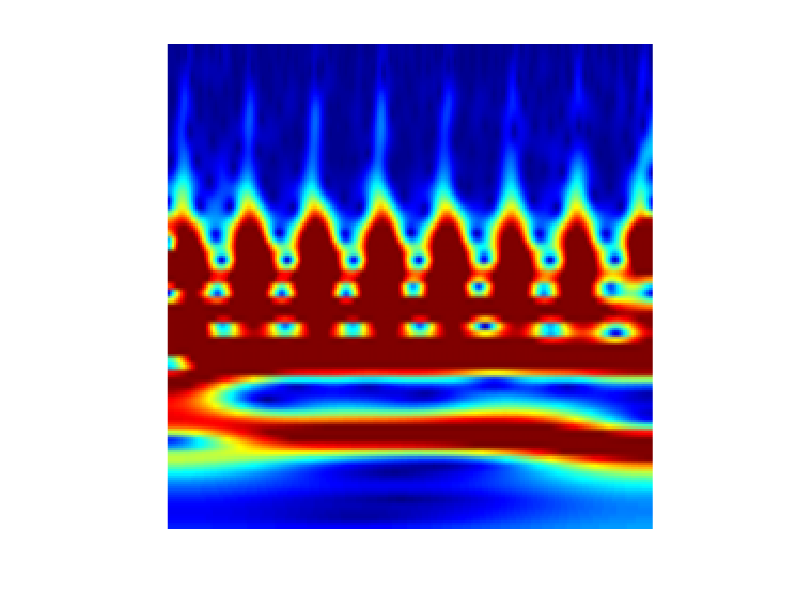

% Display the selected CHF image
imshow(chfImages{imageIndex});

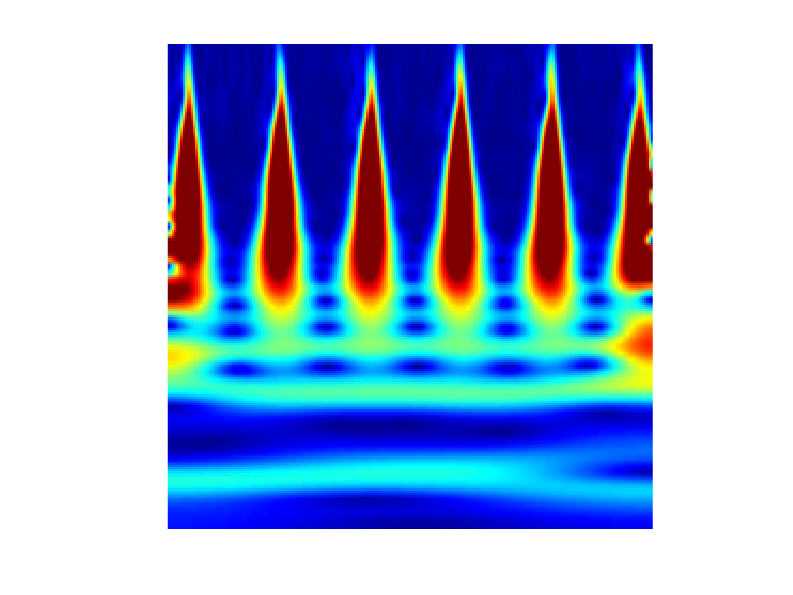


% Display the selected NSR image
imshow(nsrImages{imageIndex});

#### Divide Images into Train and Test Images

% Randomly select indices for training and test images
% Total Images for each Signal is 300. 
% Images are randomly split into two sections:
% - Train = 250 images
% - Test  = 50 images

numTrainFiles = 250;
numTestFiles = 50;

%number of images
numImagesARR = numel(arrImages);
numImagesCHF = numel(chfImages);
numImagesNSR = numel(nsrImages);

% Randomly selecting images
randomIndicesARR = randperm(numImagesARR);
randomIndicesCHF = randperm(numImagesCHF);
randomIndicesNSR = randperm(numImagesNSR);

trainIndicesARR = randomIndicesARR(1:numTrainFiles);
trainIndicesCHF = randomIndicesCHF(1:numTrainFiles);
trainIndicesNSR = randomIndicesNSR(1:numTrainFiles);

testIndicesARR = randomIndicesARR(numTrainFiles+1:numTrainFiles+numTestFiles);
testIndicesCHF = randomIndicesCHF(numTrainFiles+1:numTrainFiles+numTestFiles);
testIndicesNSR = randomIndicesNSR(numTrainFiles+1:numTrainFiles+numTestFiles);

% Create training and test folders for ARR 
arrTrainFolder = 'CWT/images/train/ARR';
arrTestFolder = 'CWT/images/test/ARR';

mkdir("CWT");
mkdir(arrTrainFolder);
mkdir(arrTestFolder);

% Copy training images for ARR to the train folder
for i = 1:numTrainFiles
    imageIndex = trainIndicesARR(i);
    filename = sprintf('ARR_train_%d.jpg', imageIndex);
    filepath = fullfile(arrTrainFolder, filename);
    imwrite(arrImages{imageIndex}, filepath);
end

% Copy test images for ARR to the test folder
for i = 1:numTestFiles
    imageIndex = testIndicesARR(i);
    filename = sprintf('ARR_test_%d.jpg', imageIndex);
    filepath = fullfile(arrTestFolder, filename);
    imwrite(arrImages{imageIndex}, filepath);
end

% Create training and test folders for CHF 
chfTrainFolder = 'CWT/images/train/CHF';
chfTestFolder = 'CWT/images/test/CHF';

mkdir(chfTrainFolder);
mkdir(chfTestFolder);

% Copy training images for CHF to the train folder
for i = 1:numTrainFiles
    imageIndex = trainIndicesCHF(i);
    filename = sprintf('CHF_train_%d.jpg', imageIndex);
    filepath = fullfile(chfTrainFolder, filename);
    imwrite(chfImages{imageIndex}, filepath);
end

% Copy test images for CHF to the test folder
for i = 1:numTestFiles
    imageIndex = testIndicesCHF(i);
    filename = sprintf('CHF_test_%d.jpg', imageIndex);
    filepath = fullfile(chfTestFolder, filename);
    imwrite(chfImages{imageIndex}, filepath);
end

% Create training and test folders for NSR
nsrTrainFolder = 'CWT/images/train/NSR';
nsrTestFolder = 'CWT/images/test/NSR';

mkdir(nsrTrainFolder);
mkdir(nsrTestFolder);

% Copy training images for NSR to the train folder
for i = 1:numTrainFiles
    imageIndex = trainIndicesNSR(i);
    filename = sprintf('NSR_train_%d.jpg', imageIndex);
    filepath = fullfile(nsrTrainFolder, filename);
    imwrite(nsrImages{imageIndex}, filepath);
end

% Copy test images for NSR to the test folder
for i = 1:numTestFiles
    imageIndex = testIndicesNSR(i);
    filename = sprintf('NSR_test_%d.jpg', imageIndex);
    filepath = fullfile(nsrTestFolder, filename);
    imwrite(nsrImages{imageIndex}, filepath);
end

% Create imageDatastore for training and test sets
TrainImages = imageDatastore({arrTrainFolder, chfTrainFolder, nsrTrainFolder}, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
TestImages = imageDatastore({arrTestFolder, chfTestFolder, nsrTestFolder}, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

### Design CNNs

#### **GoogleNet**

% Load the pre-trained GoogleNet network
net1 = googlenet;

%Inspect the first element of the network Layers property. GoogLeNet requires RGB images of size 224-by-224-by-3.
net1.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


%Test and Train Images are currently of size 227 by 227 by 3. 
% Resize the input images to 224 x 224 x 3.
TrainImagesResized = augmentedImageDatastore([224 224 3], TrainImages);
TestImagesResized = augmentedImageDatastore([224 224 3], TestImages);

% Create a layer graph from the network 'net1'
lgraph = layerGraph(net1);

% Determine the number of layers in the layer graph
numberOfLayers = numel(lgraph.Layers);

% Create a new dropout layer with a dropout rate of 0.6
newDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');

% Replace the layer named 'pool5-drop_7x7_s1' in the layer graph with the new dropout layer
lgraph = replaceLayer(lgraph,'pool5-drop_7x7_s1',newDropoutLayer);

% Define the number of classes
numClasses = 3;  % ARR, CHF, NSR

% A new fullyConnectedLayer is created with the specified number of classes 
% (numClasses). The WeightLearnRateFactor and BiasLearnRateFactor are set to 5.
newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);

% Replace the layer named 'loss3-classifier' in the layer graph with the new fully connected layer
lgraph = replaceLayer(lgraph,'loss3-classifier',newConnectedLayer);

% Create a new classification output layer
newClassLayer = classificationLayer('Name','new_classoutput');

% Replace the output layer in the layer graph with the new classification output layer
lgraph = replaceLayer(lgraph,'output',newClassLayer);

% Configure the training options
% The trainingOptions function is used to configure the training options. The options include:

% Using the stochastic gradient descent with momentum ('sgdm') as the optimizer.
% Setting the mini-batch size to 15.
% Setting the maximum number of epochs to 20.
% Setting the initial learning rate to 1e-4.
% Providing validation data (TestImagesResized) for monitoring the network's performance

options = trainingOptions('sgdm',...
    'MiniBatchSize',15,...
    'MaxEpochs',20,...
    'InitialLearnRate',1e-4,...
    'ValidationData',TestImagesResized,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');

% Set the random number generator seed to the default value
rng default

% Train the network using the resized training images, the modified layer graph, 
% and the specified options
TrainedGoogleNet = trainNetwork(TrainImagesResized, lgraph, options);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |       40.00% |       34.00% |       1.7301 |       1.3363 |      1.0000e-04 |
|       1 |          10 |       00:00:19 |       26.67% |       47.33% |       1.6090 |       1.1275 |      1.0000e-04 |
|       1 |          20 |       00:00:29 |       73.33% |       59.33% |       0.6977 |       0.9405 |      1.0000e-04 |
|       1 |          30 |       00:00:39 |       46.67% |       68.00% |       1.2415 |       0.7068 |      1.0000

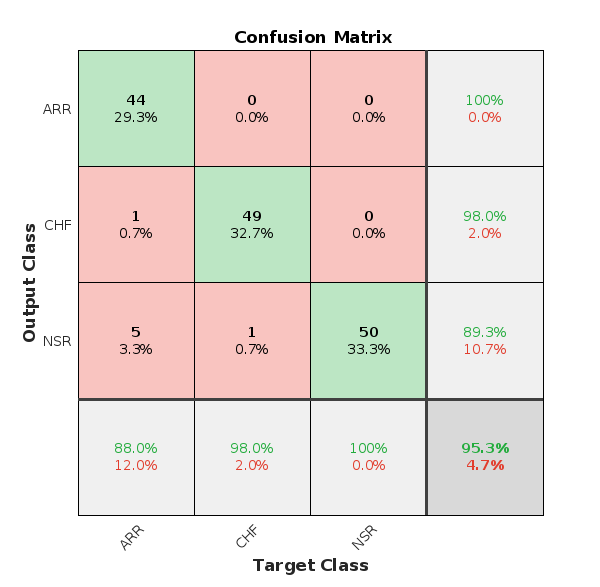

% Classify the test images
YPred = classify(TrainedGoogleNet, TestImagesResized);
YValidation = TestImages.Labels;

% Calculate accuracy
GoogleNet_Accuracy = sum(YPred == YValidation) / numel(YValidation);

% Plot confusion matrix
plotconfusion(YValidation, YPred);

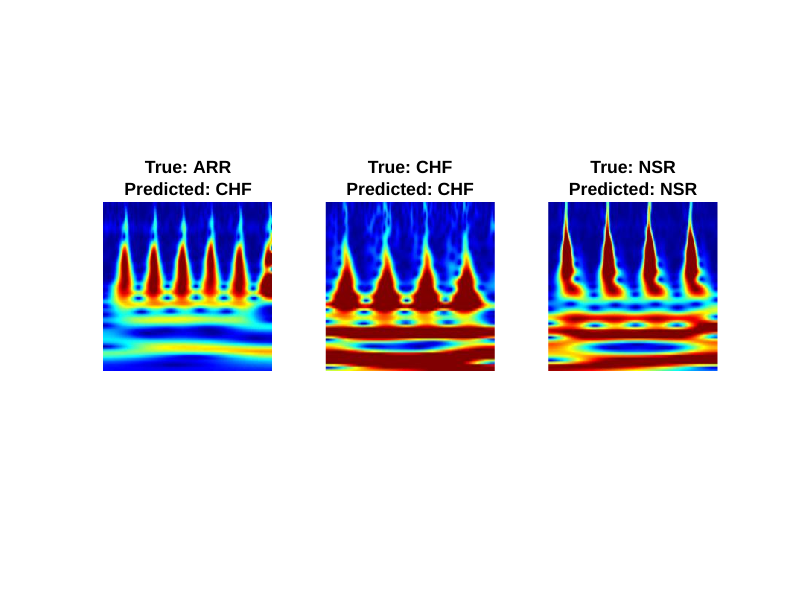

% Display sample predictions

% Select specific images from the test set

% Total number of test images = 150

                %ARR  %CHF  %NSR
imageIndices = [ 10  , 70 ,  120  ];  % Indices of the images you want to visualize

% Display the selected images and their predictions
numImages = numel(imageIndices);
figure;
for i = 1:numImages
    % Read the image
    img = imread(TestImages.Files{imageIndices(i)});
    
    % Display the image
    subplot(1, numImages, i);
    imshow(img);
    title(sprintf('True: %s\nPredicted: %s', char(TestImages.Labels(imageIndices(i))), char(YPred(imageIndices(i)))));
end

#### **SqueezeNet**

% Load the pre-trained SqueezeNet network
net2 = squeezenet;

%Inspect the first element of the network Layers property. SqueezeNet requires RGB images of size 227-by-227-by-3
net2.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [227 227 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [1×1×3 single]


%Test and Train Images are currently of size 227 by 227 by 3. 

% Define the number of classes as 3 (ARR, CHF, NSR)
numClasses = 3; 

% Create a layer graph from the network 'net2'. 
% The layerGraph object represents the [network's architecture and
% allows for easy manipulation of the network layers.
lgraphSqz = layerGraph(net2);

% Inspect the last six network layers. The indexing end-5:end specifies 
% a range from the sixth-to-last layer to the last layer.
lgraphSqz.Layers(end-5:end)

ans =   6×1 Layer array with layers:

     1   'drop9'                             Dropout                      50% dropout
     2   'conv10'                            2-D Convolution              1000 1×1×512 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'                       ReLU                         ReLU
     4   'pool10'                            2-D Global Average Pooling   2-D global average pooling
     5   'prob'                              Softmax                      softmax
     6   'ClassificationLayer_predictions'   Classification Output        crossentropyex with 'tench' and 999 other classes

% Define the layers for the new network

% Get the sixth-to-last layer from the layer graph
tmpLayer = lgraphSqz.Layers(end-5);

% Create a new dropout layer with a dropout rate of 0.6 and name it 'new_dropout'
newDropoutLayer = dropoutLayer(0.6,'Name','new_dropout');

% Replace the sixth-to-last layer in the layer graph with the new dropout layer
lgraphSqz = replaceLayer(lgraphSqz, tmpLayer.Name, newDropoutLayer);


% Get the fifth-to-last layer from the layer graph
tmpLayer = lgraphSqz.Layers(end-4);

% Create a new learnable convolutional layer with 1 filter and numClasses outputs
% Set the name as 'new_conv' and the learn rate factors for weights and biases as 10
newLearnableLayer = convolution2dLayer(1, numClasses, ...
        'Name', 'new_conv', ...
        'WeightLearnRateFactor', 10, ...
        'BiasLearnRateFactor', 10);

% Replace the fifth-to-last layer in the layer graph with the new learnable convolutional layer
lgraphSqz = replaceLayer(lgraphSqz, tmpLayer.Name, newLearnableLayer);


% Get the last layer from the layer graph
tmpLayer = lgraphSqz.Layers(end);

% Create a new classification output layer with the name 'new_classoutput'
newClassLayer = classificationLayer('Name', 'new_classoutput');

% Replace the last layer in the layer graph with the new classification output layer
lgraphSqz = replaceLayer(lgraphSqz, tmpLayer.Name, newClassLayer);


% Extract and inspect a subset of layers in the modified layer graph
lgraphSqz.Layers(63:68);
% Set training options

% Set the initial learning rate
% ilr (initial learning rate) is set to 3e-4, 
% which determines the step size at the beginning of training.
ilr = 3e-4;

% Set the mini-batch size. Smaller batch sizes can provide more
% frequent updates to the network but may increase training time.
miniBatchSize = 10;

% Set the maximum number of training epochs
% maxEpochs is set to 15, which determines the maximum number of 
% complete passes through the training dataset during training.
maxEpochs = 15;

% Calculate the validation frequency based on the number of training images and the mini-batch size
valFreq = floor(numel(TrainImages.Files) / miniBatchSize);


% Configure the training options.

% The 'sgdm' solver (stochastic gradient descent with momentum) is specified, 
% along with the previously defined parameters.

% Verbose is set to 1, which enables the display of 
% training progress information during training.

% ExecutionEnvironment is set to 'cpu', which indicates 
% that the training should be performed using the CPU.

% Plots is set to 'training-progress', which displays training 
% progress plots, including the loss and accuracy curves, during training.
options = trainingOptions('sgdm',...
    'MiniBatchSize', miniBatchSize,...
    'MaxEpochs', maxEpochs,...
    'InitialLearnRate', ilr,...
    'ValidationData', TestImages,...
    'ValidationFrequency', valFreq,...
    'Verbose', 1,...
    'ExecutionEnvironment', 'cpu',...
    'Plots', 'training-progress');

% rng default sets the random number generator to its default 
% settings, ensuring reproducibility of the training results.
rng default

% Train the network using the specified training images, modified layer graph
% (lgraphSqz), and training options
TrainedSqueezeNet = trainNetwork(TrainImages, lgraphSqz, options);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       60.00% |       26.67% |       1.8990 |       2.8646 |          0.0003 |
|       1 |          50 |       00:00:17 |       80.00% |              |       0.5296 |              |          0.0003 |
|       1 |          75 |       00:00:25 |       80.00% |       73.33% |       0.4146 |       0.6910 |          0.0003 |
|       2 |         100 |       00:00:30 |       60.00% |              |       0.6465 |              |          0.

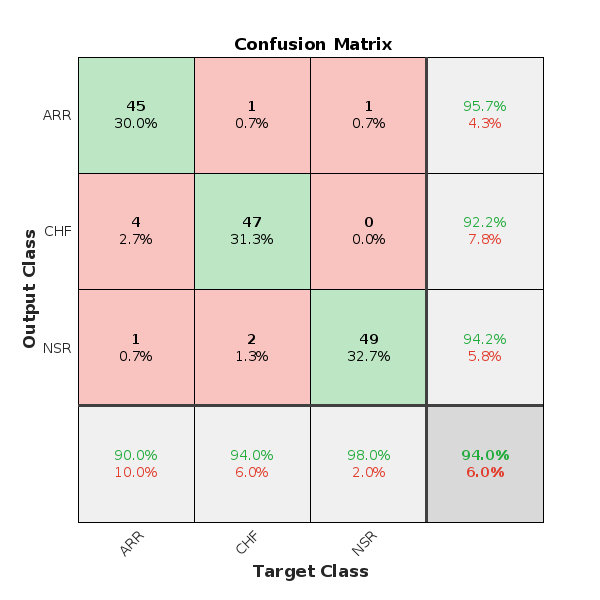

% Classify the test images
YPred = classify(TrainedSqueezeNet, TestImages);
YValidation = TestImages.Labels;

% Calculate accuracy
SqueezeNet_Accuracy = sum(YPred == YValidation) / numel(YValidation);

% Plot confusion matrix
plotconfusion(YValidation, YPred);

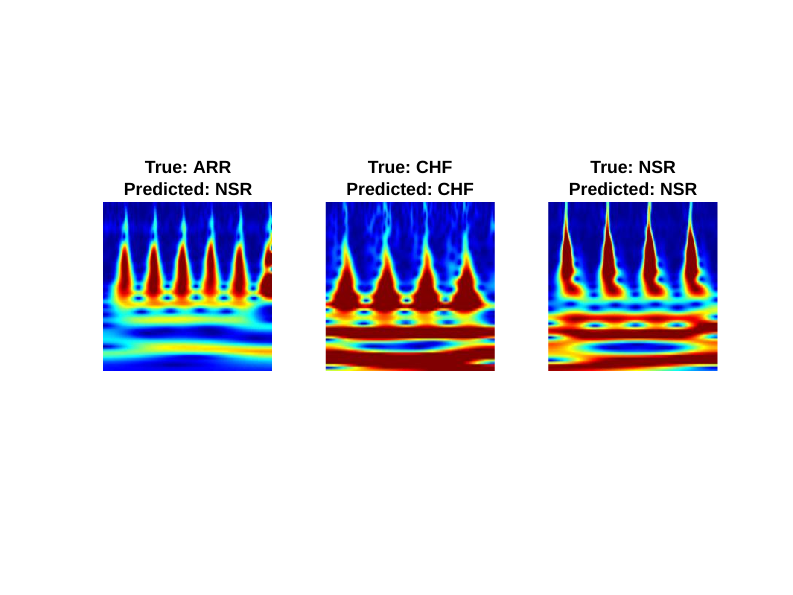

% Display sample predictions

% Select specific images from the test set

% Total number of test images = 150

                %ARR  %CHF  %NSR
imageIndices = [ 10  , 70 ,  120  ];  % Indices of the images you want to visualize

% Display the selected images and their predictions
numImages = numel(imageIndices);
figure;
for i = 1:numImages
    % Read the image
    img = imread(TestImages.Files{imageIndices(i)});
    
    % Display the image
    subplot(1, numImages, i);
    imshow(img);
    title(sprintf('True: %s\nPredicted: %s', char(TestImages.Labels(imageIndices(i))), char(YPred(imageIndices(i)))));
end

#### **AlexNet**

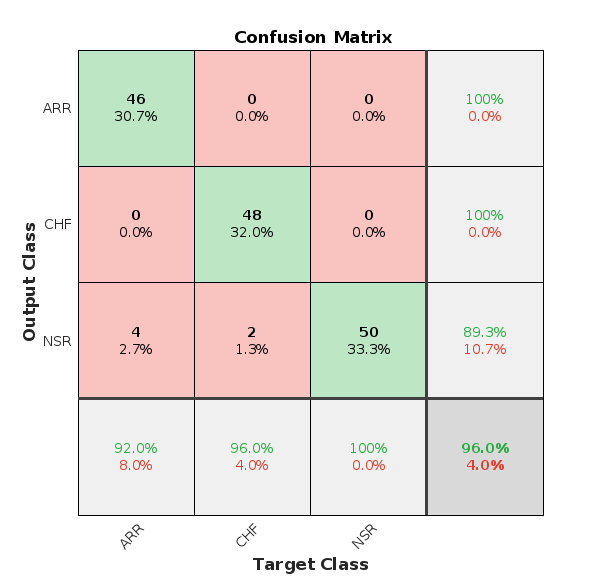

%AlexNet
net3 = alexnet;

% Inspect the first element of the network Layers property. AlexNet requires 
% RGB images of size 227-by-227-by-3
net3.Layers(1);

%Test and Train Images are currently of size 227 by 227 by 3. 

% Preserve all layers except the last three layers
layersTransfer = net3.Layers(1:end-3);

% Define the number of classes as 3 (ARR, CHF, NSR)
numClasses = 3;

% Define the layers of AlexNet

% The layers variable is defined to create a new layer 
% architecture for fine-tuning. It starts with the preserved layers 
% from layersTransfer, followed by a fully connected layer with numClasses 
% outputs. The 'WeightLearnRateFactor' and 'BiasLearnRateFactor' parameters 
% are set to 20, which means that the learning rates for these layers will be 
% increased by a factor of 20 compared to the rest of the network. This gives the 
% new fully connected layer more influence during fine-tuning. The softmaxLayer and 
% classificationLayer are added to complete the network architecture.
layers = [layersTransfer
    fullyConnectedLayer(numClasses, 'WeightLearnRateFactor', 20, 'BiasLearnRateFactor', 20)
    softmaxLayer
    classificationLayer];


% Set the training options

% The options variable is defined to set the training options for fine-tuning. 
% The 'sgdm' solver is used, which is stochastic gradient descent with momentum.
% Other options include the mini-batch size of 20, maximum number of epochs as 8, 
% initial learning rate as 1e-4, shuffling of data at every epoch, validation data 
% specified as TestImages, validation frequency of 10 mini-batches, verbose mode turned off 
% (false), and training progress plots displayed using 'training-progress'.
options = trainingOptions('sgdm', ...
    'MiniBatchSize', 20, ...
    'MaxEpochs', 8, ...
    'InitialLearnRate', 1e-4, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', TestImages, ...
    'ValidationFrequency', 10, ...
    'Verbose', false, ...
    'Plots', 'training-progress');


% Training Alexnet
TrainedAlexNet = trainNetwork(TrainImages, layers, options);

% Classify the test images 
YPred = classify(TrainedAlexNet, TestImages);
YValidation = TestImages.Labels;

% Calculate Accuracy
AlexNet_Accuracy = sum(YPred == YValidation)/numel(YValidation);

% Plotting Confusion Matrix
plotconfusion(YValidation, YPred)

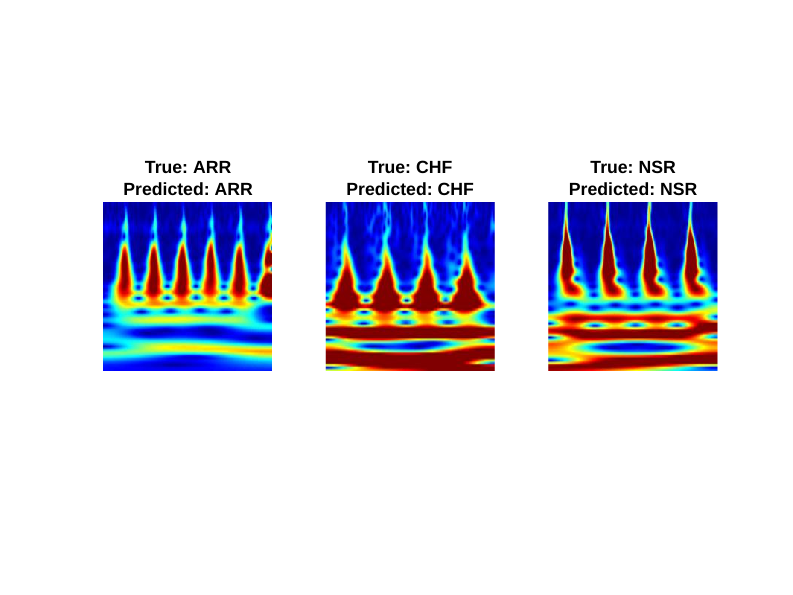

% Display sample predictions

% Select specific images from the test set

% Total number of test images = 150

                %ARR  %CHF  %NSR
imageIndices = [ 10  , 70 ,  120  ];  % Indices of the images you want to visualize

% Display the selected images and their predictions
numImages = numel(imageIndices);
figure;
for i = 1:numImages
    % Read the image
    img = imread(TestImages.Files{imageIndices(i)});
    
    % Display the image
    subplot(1, numImages, i);
    imshow(img);
    title(sprintf('True: %s\nPredicted: %s', char(TestImages.Labels(imageIndices(i))), char(YPred(imageIndices(i)))));
end

## Short Time Fourier Transformation **(STFT)**

### **ECG Signals Database Preparartion**

close all
clear all

if isfolder('STFT')
    rmdir('STFT', 's');
end


%ECG Database
load ('ECGData.mat'); % Loading ECG database

data = ECGData.Data; % Getting Database
% The variable "data" is a matrix of 162 x 65536. It means it carries
% a total of 162 ECG signals of size 65536 samples each. 


labels = ECGData.Labels; %Getting Labels
% From Labels, we get types of ECG signals information.That is,

% 1:96 are ARR Signals (96)
% 97:126 are CHF Signals (30)
% 127:162 are NSR Signals (36)



% Each recording is of 65,536 samples therefore, it can be broken 
% into small signals of length 500 samples to increase the size of
% database to make it appropriate to train a CNN. 

% For this purpose, we take 30 recordings of each type (ARR, CHF, 
% NSR) to have equal distribution. Each recording is broken in to
% 10 pieces of length of 500 samples. Therefore, each category will
% provide 300 recordings of size 500 samples and total will be 900 
% recordings. Out of 900 (30x10) recordings, 750 will be used for 
% training and 150 will be used for testing.

ARR = data (1:30,:); %Taken first 30 Recordings
CHF = data (97:126, :); %Taken first 30 Recordings
NSR = data (127:156, :); %Taken first 30 Recordings

#### Plot the Signals

% Plot ARR
plot(ARR(1, 1:1000));
title('ARR');
grid on

% Plot CHF
plot(CHF(1, 1:1000));
title('CHF');
grid on

% Plot NSR
plot(NSR(1, 1:1000));
title('NSR');
grid on

#### Short Time Fourier Transformation (STFT)

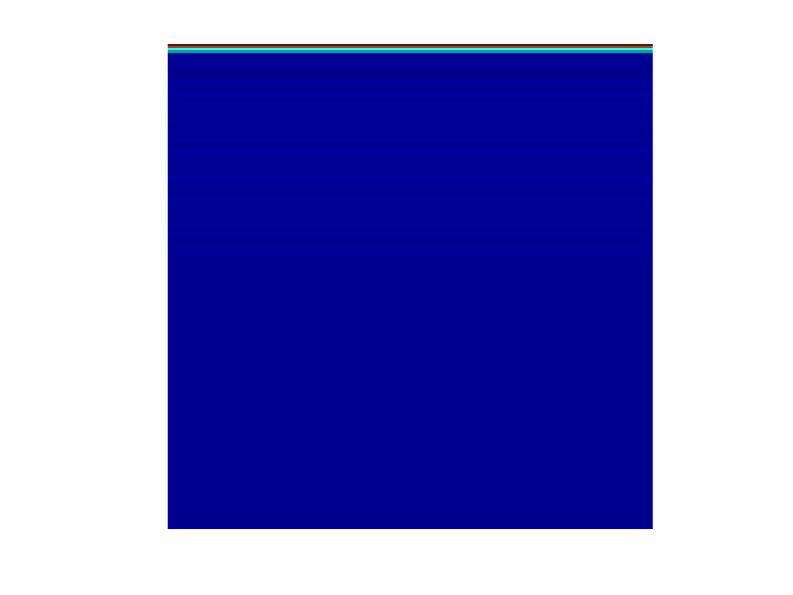

% Define parameters for STFT
windowLength = 256; % Window length for STFT
% 'windowLength' is set to 256, which determines the length of the 
% window used for computing the STFT. A larger window length provides higher 
% frequency resolution but lower time resolution.

overlapRatio = 0.5; % Overlap ratio between consecutive windows
% 'overlapRatio' is set to 0.5, which represents the ratio of overlap between 
% consecutive windows. A higher overlap ratio increases the time resolution but
% may introduce more redundancy in the STFT.

Fs = 10e3; % Sampling frequency
 % 'Fs' (sampling frequency) is set to 10e3 (10,000), which represents 
 % the rate at which the ECG data is sampled. It is necessary for correctly
 % interpreting the frequency content of the STFT.


% The 'ecg2stft' function takes the ECG data, window length, overlap ratio, and 
% sampling frequency as input parameters.
% - The output of each function call is stored in separate variables: 'arrImages', 
%   'chfImages', and 'nsrImages'.
% - These variables contain the generated STFT images for the corresponding ECG data. 
% - Images of size 227 x 227 x 3

% Compute STFT for ARR data
arrImages = ecg2stft(ARR, windowLength, overlapRatio, Fs);

% Compute STFT for CHF data
chfImages = ecg2stft(CHF, windowLength, overlapRatio, Fs);

% Compute STFT for NSR data
nsrImages = ecg2stft(NSR, windowLength, overlapRatio, Fs);

% A cell array that stores the generated STFT images.



%Display sample of each ARR, CHF, NSR
imageIndex = 98;

% Display the selected ARR image
imshow(arrImages{imageIndex});

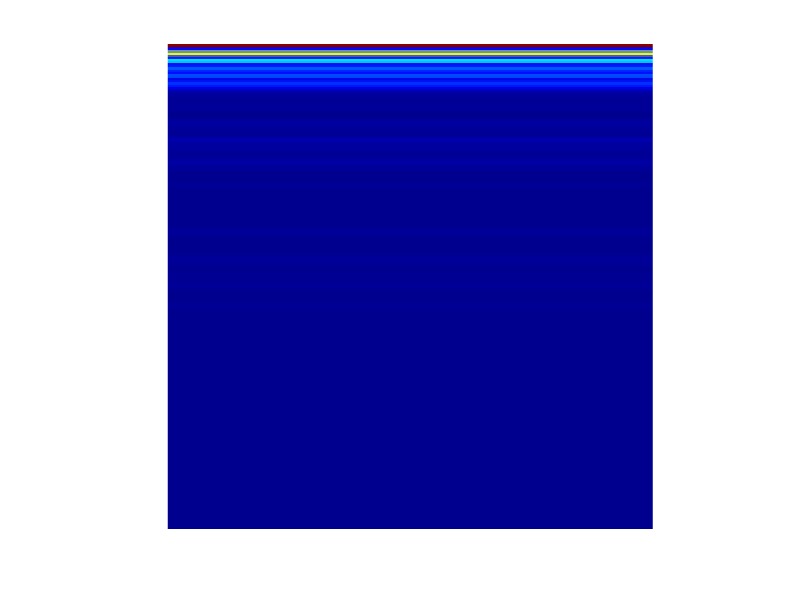


% Display the selected CHF image
imshow(chfImages{imageIndex});

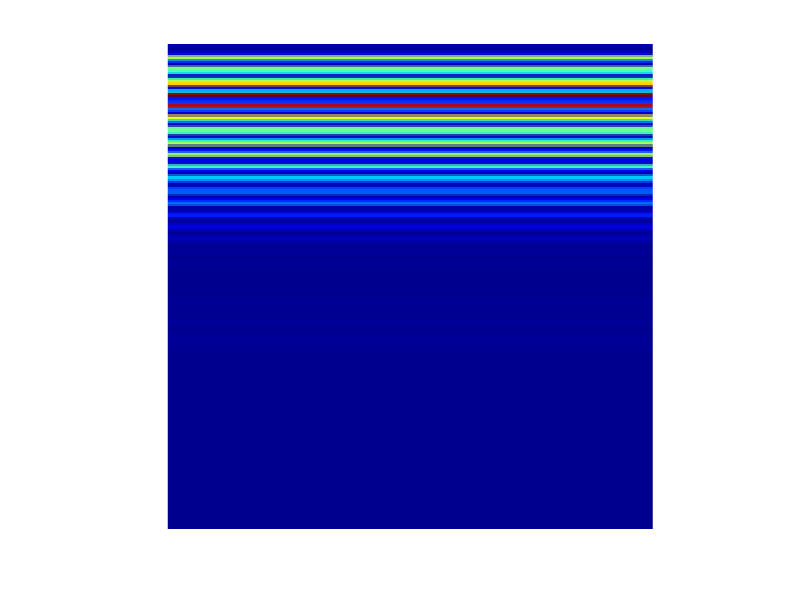


% Display the selected NSR image
imshow(nsrImages{imageIndex});

#### Divide Images into Train and Test Images

% Randomly select indices for training and test images
% Total Images for each Signal is 300. 
% Images are randomly split into two sections:
% - Train = 250 images
% - Test  = 50 images

% Randomly select indices for training and test images
numTrainFiles = 250;
numTestFiles = 50;

%Total number of images for each signal is 300
numImagesARR = numel(arrImages);
numImagesCHF = numel(chfImages);
numImagesNSR = numel(nsrImages);

% Randomly selecting images
randomIndicesARR = randperm(numImagesARR);
randomIndicesCHF = randperm(numImagesCHF);
randomIndicesNSR = randperm(numImagesNSR);

trainIndicesARR = randomIndicesARR(1:numTrainFiles);
trainIndicesCHF = randomIndicesCHF(1:numTrainFiles);
trainIndicesNSR = randomIndicesNSR(1:numTrainFiles);

testIndicesARR = randomIndicesARR(numTrainFiles+1:numTrainFiles+numTestFiles);
testIndicesCHF = randomIndicesCHF(numTrainFiles+1:numTrainFiles+numTestFiles);
testIndicesNSR = randomIndicesNSR(numTrainFiles+1:numTrainFiles+numTestFiles);

% Create training and test folders for ARR
arrTrainFolder = 'STFT/images/train/ARR';
arrTestFolder = 'STFT/images/test/ARR';

mkdir("STFT");
mkdir(arrTrainFolder);
mkdir(arrTestFolder);

% Copy training images for ARR to the train folder
for i = 1:numTrainFiles
    imageIndex = trainIndicesARR(i);
    filename = sprintf('ARR_train_%d.jpg', imageIndex);
    filepath = fullfile(arrTrainFolder, filename);
    imwrite(arrImages{imageIndex}, filepath);
end

% Copy test images for ARR to the test folder
for i = 1:numTestFiles
    imageIndex = testIndicesARR(i);
    filename = sprintf('ARR_test_%d.jpg', imageIndex);
    filepath = fullfile(arrTestFolder, filename);
    imwrite(arrImages{imageIndex}, filepath);
end

% Create training and test folders for CHF
chfTrainFolder = 'STFT/images/train/CHF';
chfTestFolder = 'STFT/images/test/CHF';

mkdir(chfTrainFolder);
mkdir(chfTestFolder);

% Copy training images for CHF to the train folder
for i = 1:numTrainFiles
    imageIndex = trainIndicesCHF(i);
    filename = sprintf('CHF_train_%d.jpg', imageIndex);
    filepath = fullfile(chfTrainFolder, filename);
    imwrite(chfImages{imageIndex}, filepath);
end

% Copy test images for CHF to the test folder
for i = 1:numTestFiles
    imageIndex = testIndicesCHF(i);
    filename = sprintf('CHF_test_%d.jpg', imageIndex);
    filepath = fullfile(chfTestFolder, filename);
    imwrite(chfImages{imageIndex}, filepath);
end

% Create training and test folders for NSR
nsrTrainFolder = 'STFT/images/train/NSR';
nsrTestFolder = 'STFT/images/test/NSR';

mkdir(nsrTrainFolder);
mkdir(nsrTestFolder);

% Copy training images for NSR to the train folder
for i = 1:numTrainFiles
    imageIndex = trainIndicesNSR(i);
    filename = sprintf('NSR_train_%d.jpg', imageIndex);
    filepath = fullfile(nsrTrainFolder, filename);
    imwrite(nsrImages{imageIndex}, filepath);
end

% Copy test images for NSR to the test folder
for i = 1:numTestFiles
    imageIndex = testIndicesNSR(i);
    filename = sprintf('NSR_test_%d.jpg', imageIndex);
    filepath = fullfile(nsrTestFolder, filename);
    imwrite(nsrImages{imageIndex}, filepath);
end

% Create imageDatastore for training and test sets
TrainImages = imageDatastore({arrTrainFolder, chfTrainFolder, nsrTrainFolder}, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
TestImages = imageDatastore({arrTestFolder, chfTestFolder, nsrTestFolder}, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

### Design CNNs

#### **GoogleNet**

% Load the pre-trained GoogleNet network
net1 = googlenet;

%Inspect the first element of the network Layers property. GoogLeNet requires RGB images of size 224-by-224-by-3.
net1.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


%Test and Train Images are currently of size 227 by 227 by 3. 
% Resize the input images to 224 x 224 x 3.
TrainImagesResized = augmentedImageDatastore([224 224 3], TrainImages);
TestImagesResized = augmentedImageDatastore([224 224 3], TestImages);

% Create a layer graph from the network 'net1'
lgraph = layerGraph(net1);

% Determine the number of layers in the layer graph
numberOfLayers = numel(lgraph.Layers);

% Create a new dropout layer with a dropout rate of 0.6
newDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');

% Replace the layer named 'pool5-drop_7x7_s1' in the layer graph with the new dropout layer
lgraph = replaceLayer(lgraph,'pool5-drop_7x7_s1',newDropoutLayer);

% Define the number of classes
numClasses = 3;  % ARR, CHF, NSR

% A new fullyConnectedLayer is created with the specified number of classes 
% (numClasses). The WeightLearnRateFactor and BiasLearnRateFactor are set to 5.
newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);

% Replace the layer named 'loss3-classifier' in the layer graph with the new fully connected layer
lgraph = replaceLayer(lgraph,'loss3-classifier',newConnectedLayer);

% Create a new classification output layer
newClassLayer = classificationLayer('Name','new_classoutput');

% Replace the output layer in the layer graph with the new classification output layer
lgraph = replaceLayer(lgraph,'output',newClassLayer);

% Configure the training options
% The trainingOptions function is used to configure the training options. The options include:

% Using the stochastic gradient descent with momentum ('sgdm') as the optimizer.
% Setting the mini-batch size to 15.
% Setting the maximum number of epochs to 20.
% Setting the initial learning rate to 1e-4.
% Providing validation data (TestImagesResized) for monitoring the network's performance

options = trainingOptions('sgdm',...
    'MiniBatchSize',15,...
    'MaxEpochs',20,...
    'InitialLearnRate',1e-4,...
    'ValidationData',TestImagesResized,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');

% Set the random number generator seed to the default value
rng default

% Train the network using the resized training images, the modified layer graph, 
% and the specified options
TrainedGoogleNet = trainNetwork(TrainImagesResized, lgraph, options);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |       40.00% |       33.33% |       1.6633 |       1.5262 |      1.0000e-04 |
|       1 |          10 |       00:00:18 |       60.00% |       86.00% |       0.8516 |       0.5149 |      1.0000e-04 |
|       1 |          20 |       00:00:30 |       66.67% |       90.67% |       0.5534 |       0.2947 |      1.0000e-04 |
|       1 |          30 |       00:00:43 |       66.67% |       93.33% |       0.7389 |       0.2281 |      1.0000

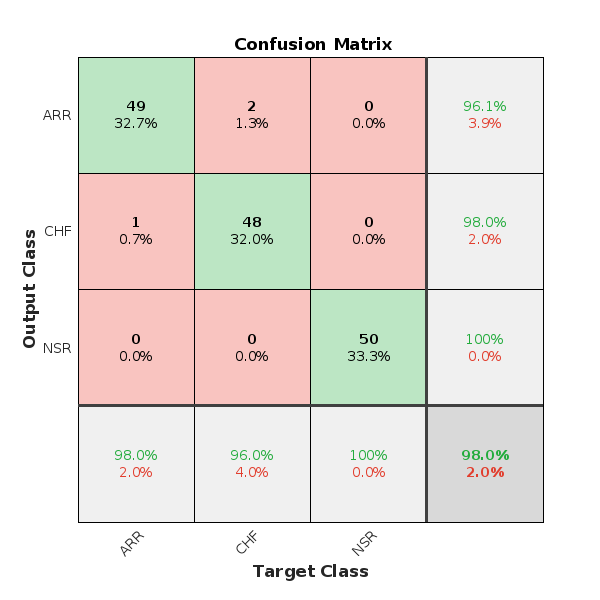

% Classify the test images
YPred = classify(TrainedGoogleNet, TestImagesResized);
YValidation = TestImages.Labels;

% Calculate accuracy
GoogleNet_Accuracy = sum(YPred == YValidation) / numel(YValidation);

% Plot confusion matrix
plotconfusion(YValidation, YPred)

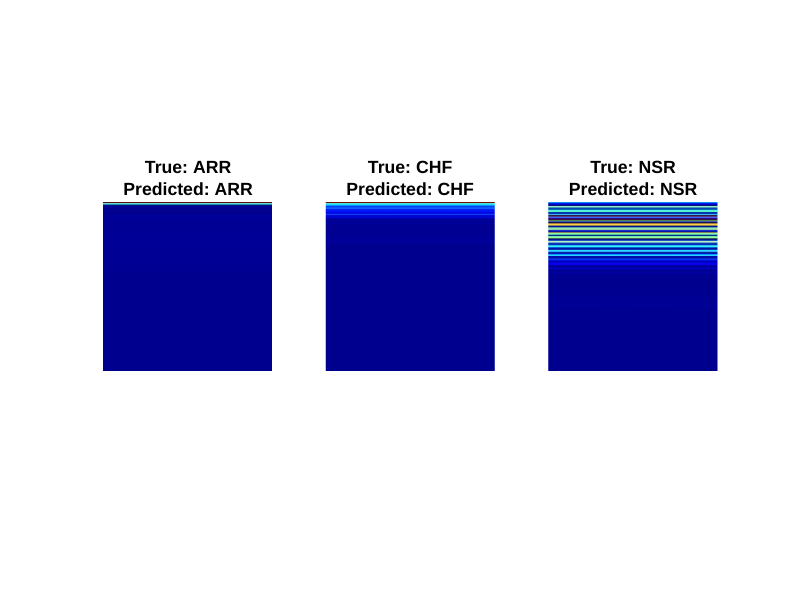



% Display sample predictions

% Select specific images from the test set

% Total number of test images = 150

                %ARR  %CHF  %NSR
imageIndices = [ 10  , 70 ,  120  ];  % Indices of the images you want to visualize

% Display the selected images and their predictions
numImages = numel(imageIndices);
figure;
for i = 1:numImages
    % Read the image
    img = imread(TestImages.Files{imageIndices(i)});
    
    % Display the image
    subplot(1, numImages, i);
    imshow(img);
    title(sprintf('True: %s\nPredicted: %s', char(TestImages.Labels(imageIndices(i))), char(YPred(imageIndices(i)))));
end

#### **SqueezeNet**

% Load the pre-trained SqueezeNet network
net2 = squeezenet;

%Inspect the first element of the network Layers property. SqueezeNet requires RGB images of size 227-by-227-by-3
net2.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [227 227 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [1×1×3 single]



%Test and Train Images are currently of size 227 by 227 by 3. 

% Define the number of classes as 3 (ARR, CHF, NSR)
numClasses = 3; 

% Create a layer graph from the network 'net2'. 
% The layerGraph object represents the [network's architecture and
% allows for easy manipulation of the network layers.
lgraphSqz = layerGraph(net2);

% Inspect the last six network layers. The indexing end-5:end specifies 
% a range from the sixth-to-last layer to the last layer.
lgraphSqz.Layers(end-5:end)

ans =   6×1 Layer array with layers:

     1   'drop9'                             Dropout                      50% dropout
     2   'conv10'                            2-D Convolution              1000 1×1×512 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'                       ReLU                         ReLU
     4   'pool10'                            2-D Global Average Pooling   2-D global average pooling
     5   'prob'                              Softmax                      softmax
     6   'ClassificationLayer_predictions'   Classification Output        crossentropyex with 'tench' and 999 other classes

% Define the layers for the new network

% Get the sixth-to-last layer from the layer graph
tmpLayer = lgraphSqz.Layers(end-5);

% Create a new dropout layer with a dropout rate of 0.6 and name it 'new_dropout'
newDropoutLayer = dropoutLayer(0.6,'Name','new_dropout');

% Replace the sixth-to-last layer in the layer graph with the new dropout layer
lgraphSqz = replaceLayer(lgraphSqz, tmpLayer.Name, newDropoutLayer);


% Get the fifth-to-last layer from the layer graph
tmpLayer = lgraphSqz.Layers(end-4);

% Create a new learnable convolutional layer with 1 filter and numClasses outputs
% Set the name as 'new_conv' and the learn rate factors for weights and biases as 10
newLearnableLayer = convolution2dLayer(1, numClasses, ...
        'Name', 'new_conv', ...
        'WeightLearnRateFactor', 10, ...
        'BiasLearnRateFactor', 10);

% Replace the fifth-to-last layer in the layer graph with the new learnable convolutional layer
lgraphSqz = replaceLayer(lgraphSqz, tmpLayer.Name, newLearnableLayer);


% Get the last layer from the layer graph
tmpLayer = lgraphSqz.Layers(end);

% Create a new classification output layer with the name 'new_classoutput'
newClassLayer = classificationLayer('Name', 'new_classoutput');

% Replace the last layer in the layer graph with the new classification output layer
lgraphSqz = replaceLayer(lgraphSqz, tmpLayer.Name, newClassLayer);


% Extract and inspect a subset of layers in the modified layer graph
lgraphSqz.Layers(63:68);
% Set training options

% Set the initial learning rate
% ilr (initial learning rate) is set to 3e-4, 
% which determines the step size at the beginning of training.
ilr = 3e-4;

% Set the mini-batch size. Smaller batch sizes can provide more
% frequent updates to the network but may increase training time.
miniBatchSize = 10;

% Set the maximum number of training epochs
% maxEpochs is set to 15, which determines the maximum number of 
% complete passes through the training dataset during training.
maxEpochs = 15;

% Calculate the validation frequency based on the number of training images and the mini-batch size
valFreq = floor(numel(TrainImages.Files) / miniBatchSize);


% Configure the training options.

% The 'sgdm' solver (stochastic gradient descent with momentum) is specified, 
% along with the previously defined parameters.

% Verbose is set to 1, which enables the display of 
% training progress information during training.

% ExecutionEnvironment is set to 'cpu', which indicates 
% that the training should be performed using the CPU.

% Plots is set to 'training-progress', which displays training 
% progress plots, including the loss and accuracy curves, during training.
options = trainingOptions('sgdm',...
    'MiniBatchSize', miniBatchSize,...
    'MaxEpochs', maxEpochs,...
    'InitialLearnRate', ilr,...
    'ValidationData', TestImages,...
    'ValidationFrequency', valFreq,...
    'Verbose', 1,...
    'ExecutionEnvironment', 'cpu',...
    'Plots', 'training-progress');

% rng default sets the random number generator to its default 
% settings, ensuring reproducibility of the training results.
rng default

% Train the network using the specified training images, modified layer graph
% (lgraphSqz), and training options
TrainedSqueezeNet = trainNetwork(TrainImages, lgraphSqz, options);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       30.00% |       55.33% |       1.6288 |       1.1089 |          0.0003 |
|       1 |          50 |       00:00:17 |      100.00% |              |       0.0115 |              |          0.0003 |
|       1 |          75 |       00:00:23 |       80.00% |       95.33% |       0.6851 |       0.1617 |          0.0003 |
|       2 |         100 |       00:00:29 |      100.00% |              |       0.1401 |              |          0.

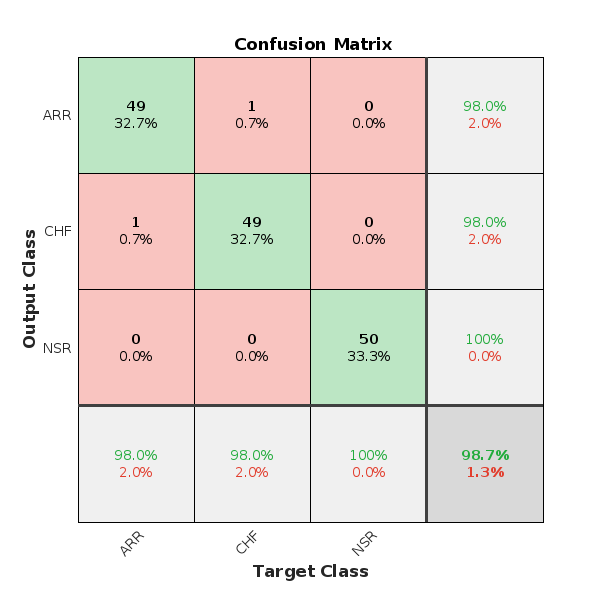

% Classify the test images
YPred = classify(TrainedSqueezeNet, TestImages);
YValidation = TestImages.Labels;

% Calculate accuracy
SqueezeNet_Accuracy = sum(YPred == YValidation) / numel(YValidation);

% Plot confusion matrix
plotconfusion(YValidation, YPred);



% Display sample predictions

% Select specific images from the test set

% Total number of test images = 150

                %ARR  %CHF  %NSR
imageIndices = [ 10  , 70 ,  120  ];  % Indices of the images you want to visualize

% Display the selected images and their predictions
numImages = numel(imageIndices);
figure;
for i = 1:numImages
    % Read the image
    img = imread(TestImages.Files{imageIndices(i)});
    
    % Display the image
    subplot(1, numImages, i);
    imshow(img);
    title(sprintf('True: %s\nPredicted: %s', char(TestImages.Labels(imageIndices(i))), char(YPred(imageIndices(i)))));
end

#### **AlexNet**

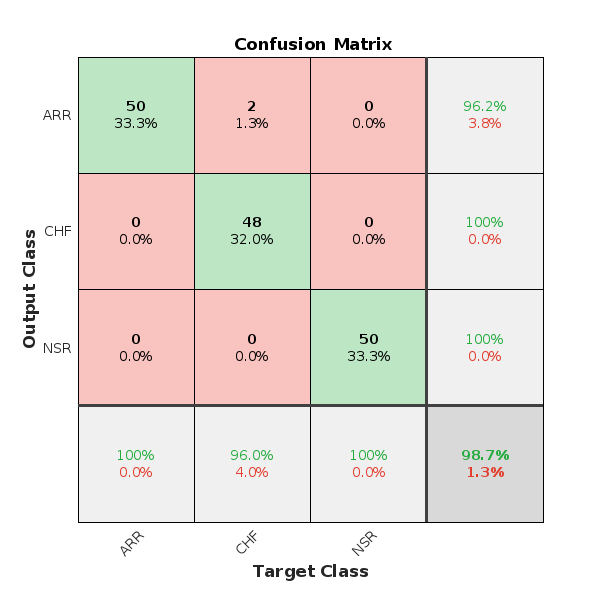

%AlexNet
net3 = alexnet;

% Inspect the first element of the network Layers property. AlexNet requires 
% RGB images of size 227-by-227-by-3
net3.Layers(1);

%Test and Train Images are currently of size 227 by 227 by 3. 

% Preserve all layers except the last three layers
layersTransfer = net3.Layers(1:end-3);

% Define the number of classes as 3 (ARR, CHF, NSR)
numClasses = 3;

% Define the layers of AlexNet

% The layers variable is defined to create a new layer 
% architecture for fine-tuning. It starts with the preserved layers 
% from layersTransfer, followed by a fully connected layer with numClasses 
% outputs. The 'WeightLearnRateFactor' and 'BiasLearnRateFactor' parameters 
% are set to 20, which means that the learning rates for these layers will be 
% increased by a factor of 20 compared to the rest of the network. This gives the 
% new fully connected layer more influence during fine-tuning. The softmaxLayer and 
% classificationLayer are added to complete the network architecture.
layers = [layersTransfer
    fullyConnectedLayer(numClasses, 'WeightLearnRateFactor', 20, 'BiasLearnRateFactor', 20)
    softmaxLayer
    classificationLayer];


% Set the training options

% The options variable is defined to set the training options for fine-tuning. 
% The 'sgdm' solver is used, which is stochastic gradient descent with momentum.
% Other options include the mini-batch size of 20, maximum number of epochs as 8, 
% initial learning rate as 1e-4, shuffling of data at every epoch, validation data 
% specified as TestImages, validation frequency of 10 mini-batches, verbose mode turned off 
% (false), and training progress plots displayed using 'training-progress'.
options = trainingOptions('sgdm', ...
    'MiniBatchSize', 20, ...
    'MaxEpochs', 8, ...
    'InitialLearnRate', 1e-4, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', TestImages, ...
    'ValidationFrequency', 10, ...
    'Verbose', false, ...
    'Plots', 'training-progress');


% Training Alexnet
TrainedAlexNet = trainNetwork(TrainImages, layers, options);

% Classify the test images 
YPred = classify(TrainedAlexNet, TestImages);
YValidation = TestImages.Labels;

% Calculate Accuracy
AlexNet_Accuracy = sum(YPred == YValidation)/numel(YValidation);

% Plotting Confusion Matrix
plotconfusion(YValidation, YPred)



% Display sample predictions

% Select specific images from the test set

% Total number of test images = 150

                %ARR  %CHF  %NSR
imageIndices = [ 10  , 70 ,  120  ];  % Indices of the images you want to visualize

% Display the selected images and their predictions
numImages = numel(imageIndices);
figure;
for i = 1:numImages
    % Read the image
    img = imread(TestImages.Files{imageIndices(i)});
    
    % Display the image
    subplot(1, numImages, i);
    imshow(img);
    title(sprintf('True: %s\nPredicted: %s', char(TestImages.Labels(imageIndices(i))), char(YPred(imageIndices(i)))));
end